## Data Input


close all;
clear all;
colors=npg(10); % Ten basic colors 

maindir='\\Artemis-pc\e\Data\2024-12-20\Abs-263\';   % 相位数据
main_dir_0=maindir;
load([maindir,'\population.mat']);

maindir='\\Artemis-pc\e\Data\2024-12-16\Abs-276\';   % 对比度
load([maindir,'\FitResult.mat']);



tau_single = 27;   % 单组时序时长
T = 10.03795;   % Interrogation time

phase_171 = (s3-s4)./(s3+s4);
phase_173 = (s1-s2)./(s1+s2);

omega_171 = 2*pi/107.5e-3;
omega_173 = 2*pi/77.8e-3;

a_171 = amp2;   % 171 对比度
a171_sigma = a_sigma2;
a_173 = amp;   % 173 对比度
a173_sigma = a_sigma;

delta_omega_171 = phase_171./T./a_171;
delta_omega_173 = phase_173./T./a_173;

freq_ratio = (delta_omega_171+omega_171)./(delta_omega_173+omega_173);


## Correlation

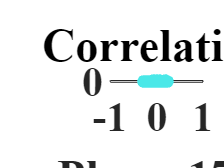


h1 = figure;
plot(phase_171,phase_173,'.','Color',[0.29,0.91,0.91],'MarkerSize',16);

xlim([-1 1]);
ylim([-1 1]);

xlabel('Phase-171');
ylabel('Phase-173');
title('Correlation','FontName','Arial','FontWeight','bold');

set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold');

set(gcf,'Visible','on');



savefig(h1,[main_dir_0,'correlation.fig']);
saveas(h1,[main_dir_0,'correlation.png']);

## Allan Deviation

两种同位素分别

### Freq Allan

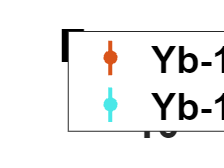


y_lim_low1 = 1e-4;

[tau_k,allan_freq_171,freq_std_171] = allan_deviation(delta_omega_171./(2*pi));
[tau_k,allan_freq_173,freq_std_173] = allan_deviation(delta_omega_173./(2*pi));

tau = tau_single.*tau_k;

h21 = figure;hold on;
I1 = errorbar(tau,allan_freq_171,freq_std_171,'.','Color',[0.85 0.33 0.1],...
    'LineWidth',1.8,'MarkerSize',20,'CapSize',0);
I2 = errorbar(tau,allan_freq_173,freq_std_173,'.','Color',[0.29,0.91,0.91],...
    'LineWidth',1.8,'MarkerSize',20,'CapSize',0);

%plot(tau,allan_freq_171,'.','Color',[0.85 0.33 0.1],'MarkerSize',20);
%plot(tau,allan_freq_173,'.','Color',[0.29,0.91,0.91],'MarkerSize',20);

legend('Yb-171','Yb-173','Location','best');

xlim([min(tau) max(tau)]);
ylim([ y_lim_low1 max([ max(allan_freq_171) , max(allan_freq_173) ])*1.2 ]);

xlabel('Interval s');
ylabel('Allan Deviation ( Hz )');
title('Frequency','FontName','Arial','FontWeight','bold');

grid on;
set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
    'XScale','log','YScale','log');

set(gcf,'Visible','on');


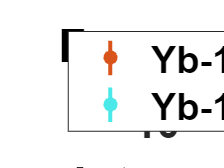


savefig(h21,[main_dir_0,'dual_freq_allan.fig']);
saveas(h21,[main_dir_0,'dual_freq_allan.png']);

### Phase Allan

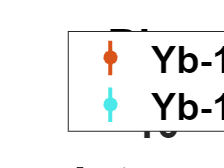


y_lim_low1 = 5e-3;

[tau_k,allan_phase_171,phase_std_171] = allan_deviation(phase_171);
[tau_k,allan_phase_173,phase_std_173] = allan_deviation(phase_173);

tau = tau_single.*tau_k;

h22 = figure;hold on;
I1 = errorbar(tau,allan_phase_171,phase_std_171,'.','Color',[0.85 0.33 0.1],...
'MarkerSize',20,'CapSize',0,'LineWidth',1.8);
I2 = errorbar(tau,allan_phase_173,phase_std_173,'.','Color',[0.29,0.91,0.91],...
'MarkerSize',20,'CapSize',0,'LineWidth',1.8);

%plot(tau,allan_phase_171,'.','Color',[0.85 0.33 0.1],'MarkerSize',20);
%plot(tau,allan_phase_173,'.','Color',[0.29,0.91,0.91],'MarkerSize',20);

legend('Yb-171','Yb-173','Location','best');

xlim([min(tau) max(tau)]);
ylim([ y_lim_low1 max([ max(allan_phase_171) , max(allan_phase_173) ])*1.2 ]);

xlabel('Interval s');
ylabel('Allan Deviation');
title('Phase','FontName','Arial','FontWeight','bold');

grid on;
set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
    'XScale','log','YScale','log');

set(gcf,'Visible','on');



savefig(h22,[main_dir_0,'dual_phase_allan.fig']);
saveas(h22,[main_dir_0,'dual_phase_allan.png']);

## Freq Ratio

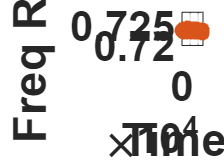


h3 = figure;
plot(tau_single.*[0:1:length(freq_ratio)-1],freq_ratio,'.','Color',[0.85 0.33 0.1],'MarkerSize',18);

xlim([min(tau) tau_single.*length(freq_ratio)]);
ylim([0.72 0.728]);
xlabel('Time s');
ylabel('Freq Ratio');
grid on;

set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
    'XScale','linear','YScale','linear');

set(gcf,'Visible','on');


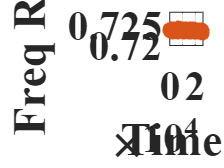


savefig(h3,[main_dir_0,'ratio.fig']);
saveas(h3,[main_dir_0,'ratio.png']);

## Allan Deviation

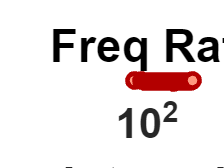


y_lim_low2 = 2.5e-5;

[tau_k,allan_ratio,allan_std_ratio] = allan_deviation(freq_ratio);
tau = tau_single.*tau_k;

h4 = figure;
I_se = errorbar(tau,allan_ratio,allan_std_ratio,'o');

I_se.CapSize = 0;
I_se.MarkerSize = 50;
I_se.LineWidth = 2;
I_se.Color = [0.5,0.4,0.3];
I_se.MarkerSize = 6;
I_se.MarkerEdgeColor = [0.7 0 0];
I_se.MarkerFaceColor = [1 0.6 0.5];

%plot(tau,allan_ratio,'.','MarkerSize',20,'Color',[0.7 0 0]);

xlim([min(tau) max(tau)]);
ylim([ y_lim_low2 max(allan_ratio)*1.1 ]);

xlabel('Interval s');
ylabel('Allan Deviation');
title('Freq Ratio','FontName','Arial','FontWeight','bold');

grid on;
set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
    'XScale','log','YScale','log');

set(gcf,'Visible','on');


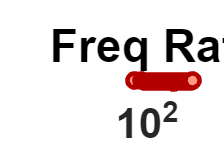


savefig(h4,[main_dir_0,'ratio_allan.fig']);
saveas(h4,[main_dir_0,'ratio_allan.png']);


save([main_dir_0,'\allan.mat']);


## Function

function [tau_k,deviation,allan_std] = allan_deviation(phase)

expon = log10(length(phase)/2);
k_list = floor(10.^[0:expon/30:expon]);

for k = 1:length(k_list)

    N = floor(length(phase)/k_list(k));
    var_total = 0;

    for m = 1:N-1
        y_m1 = mean(phase((m-1)*k_list(k)+1:m*k_list(k)));
        y_m2 = mean(phase(m*k_list(k)+1:(m+1)*k_list(k)));
        var1(m) = (y_m2-y_m1).^2;
        var_total = var_total+var1(m);
    end

    tau_k(k) = k_list(k);
    deviation(k) = sqrt(var_total/(N-1)/2);
    allan_std(k) = deviation(k)/sqrt(N+1);

end
end
